clear

addpath('functions\')

#### Compute $\Phi$

Model = myModel;

freqs = [1000 2000 4000 16000]; % (Hz)

freqs = reshape(freqs, 1,1,[]);
M = size(Model.sensors.positions,2);
N = size(Model.voxels.center,2);
Phi = zeros(M, N, length(freqs));

for k = 1:length(freqs)
    tic
    S_sigma = Model.Sensitivity(freqs(k));
    Phi(:,:,k) = -S_sigma .* Model.voxels.sigma;
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freqs(k), toc)
end

Compute 1000 Hz sensitivity took 44.75 seconds
Compute 2000 Hz sensitivity took 4.02 seconds
Compute 4000 Hz sensitivity took 3.99 seconds
Compute 16000 Hz sensitivity took 4.04 seconds



voxels_center = Model.voxels.center;

fname = sprintf('data/Phi_%s.mat', datetime('now','Format','MMdd-HHmm'));
save(fname, 'freqs','Phi','voxels_center', "-v7.3");

clear

#### Visualize $\Phi$

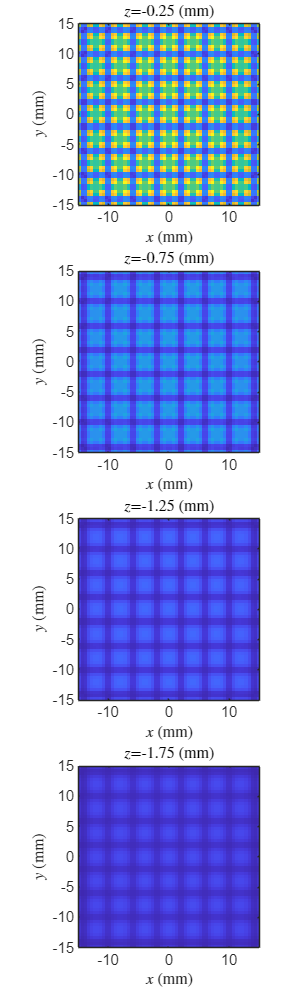

freq = 4000;

load('data\Phi.mat')
Phi = Phi(:,:,freqs == freq);
VisualizePhi(real(Phi), voxels_center)

function VisualizePhi(Phi, voxels_center, sensor_idxs)

seperate = false;

if nargin >= 3
    C = vecnorm(Phi(sensor_idxs,:), 2, 1);
else
    C = vecnorm(Phi               , 2, 1);
end

z = unique(voxels_center(3,:));
z = sort(z, 'descend');

if ~seperate
    figure
    tl = tiledlayout(length(z),1, 'TileSpacing','tight', 'Padding','none');
    set(gcf, 'Position',[10 10 flip(tl.GridSize) .* [300 250]])
end

for k = 1:length(z)
    mask = voxels_center(3,:) == z(k);
    Clayer = reshape(C(mask), sqrt(sum(mask)),[]).';

    x = [min(voxels_center(1,mask)) max(voxels_center(1,mask))] * 1e3;
    y = [min(voxels_center(2,mask)) max(voxels_center(2,mask))] * 1e3;

    if ~seperate
        nexttile
    else
        figure('Position',[10 10 900 800])
        tiledlayout(1,1, 'TileSpacing','none', 'Padding','none')
        nexttile
    end

    imagesc(x, y, Clayer, [0 max(C)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end